Consider the following system with 2 dofs [1,2]


$$\ddot{q}_1+2D_1\omega_1\dot{q}_1+\omega_1^2q_1+\frac{\omega_1^2}{2}(3q_1^2+q_2^2)+\omega_2^2q_1q_2+\frac{\omega_1^2+\omega_2^2}{2}q_1(q_1^2+q_2^2)=\epsilon f_1\cos\Omega t,\\

\ddot{q}_2+2D_2\omega_2\dot{q}_2+\omega_2^2q_2+\frac{\omega_2^2}{2}(3q_2^2+q_1^2)+\omega_1^2q_1q_2+\frac{\omega_1^2+\omega_2^2}{2}q_2(q_1^2+q_2^2)=0.$$


We select the parameters $\omega_1=2$, $\omega_2=4.5$, $D_1=0.01$ and $D_2=0.2$ and $f_1$ is set to 0.02.

The damped backbone curve is defined as


$$\mathcal{B}(\epsilon,\Omega)=\mathrm{argstat}_{\Omega} \mathcal{L}(x)$$


where $\mathcal{L}$ is an objective functional to be optimized. For example, we may use the amplitude of the first oscillator, i.e., 


$$\mathcal{L}(x)=\sqrt{\frac{1}{T}\int_0^T x_1^2(t)\mathrm{d}t}$$


or 


$$\mathcal{L}(x)=\max_{0\leq t\leq2\pi/\Omega} |x_1(t)|$$


as the objective functiona. The stationary solution of $\mathcal{L}$ gives a point on the backbone curve.

clear all

#### Setup model

[mass,damp,stiff,fnl,fext] = build_model_tensor();
DS = DynamicalSystem();
set(DS,'M',mass,'C',damp,'K',stiff,'fnl',fnl);
% Forcing
epsilon = 1;
kappas = [-1; 1];
coeffs = [fext fext]/2;
DS.add_forcing(coeffs, kappas, epsilon);

### Forced response curve


 Run='freqFRC': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.37e-02  6.08e+00    0.0    0.0    0.0
   1   1  1.00e+00  6.73e-02  3.31e-04  6.08e+00    0.0    0.0    0.0
   2   1  1.00e+00  4.83e-04  2.91e-08  6.08e+00    0.0    0.0    0.0
   3   1  1.00e+00  4.47e-08  3.68e-16  6.08e+00    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1
    0  00:00:00   6.0811e+00      1  EP      1.6000e+00   3.9270e+00   1.0000e+00   1.3897e-02
   10  00:00:00   5.5232e+00      2          1.8861e+00   3.3314e+00   1.0000e+00   4.6799e-02
   20  00:00:01   5.5142e+00      3          1.9316e+00   3.2528e+00   1.0000e+00   8.3648e-02
   30  00:00:01   5.5519e+00      4          1.9467e+00   3.2277e+00   1.0000e+00   1.1253e-01
   40  00:00:02   5.6126e+00      5       

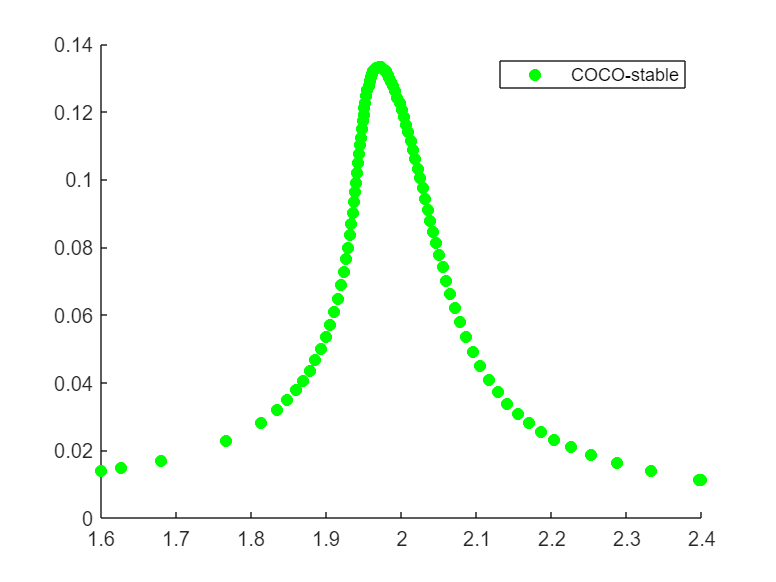

om = eig(stiff,mass);
om = sqrt(om);
freqRange = [0.8 1.2]*om(1);
nCycles = 10;
outdof = 1;
coco = cocoWrapper(DS, nCycles, outdof);
% Collocation method
set(coco.Options, 'PtMX', 250);
set(coco.Options, 'NAdapt', 2, 'h_max', 100, 'NSV',10);
coco.extract_FRC('freq',freqRange);

% Shooting method
set(coco.Options,'Nsteps',40);
coco.forward_FRC(freqRange);


 Run='forwardFRC': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.57e-02  4.64e+00    0.2    0.0    0.0
   1   1  1.00e+00  1.33e-02  1.02e-04  4.64e+00    0.4    0.2    0.0
   2   1  1.00e+00  1.28e-04  2.32e-09  4.64e+00    0.5    0.5    0.0
   3   1  1.00e+00  3.26e-09  9.05e-17  4.64e+00    0.7    0.7    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega          eps         amp1         stab
    0  00:00:02   4.6413e+00      1  EP      1.6000e+00   1.0000e+00   1.4030e-02   1.0000e+00
   10  00:00:29   4.3701e+00      2          1.9192e+00   1.0000e+00   7.2311e-02   1.0000e+00
   20  00:00:55   4.3667e+00      3          1.9421e+00   1.0000e+00   1.1081e-01   1.0000e+00
   30  00:01:18   4.3682e+00      4          1.9590e+00   1.0000e+00   1.3101e-01   1.0000e+00
   40  00:01:38   4.3621e+00      5    

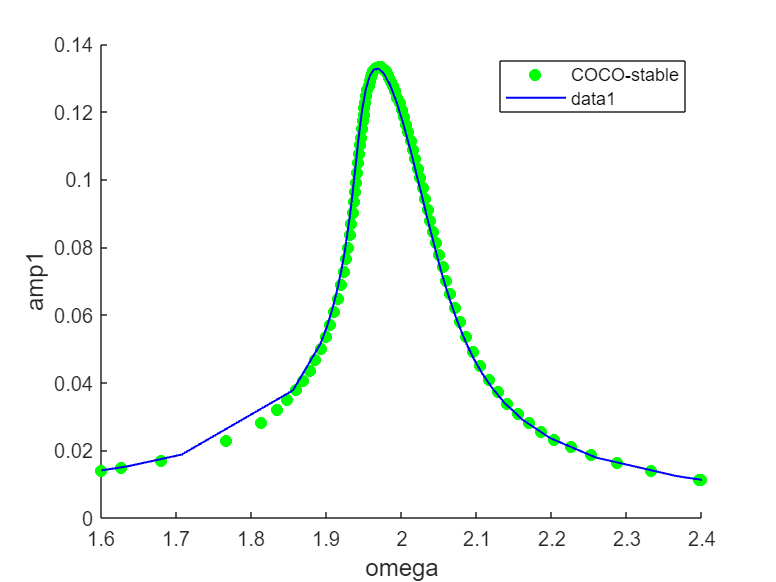

hold on
coco_plot_bd('forwardFRC','omega','amp1');

#### Damped backbone curve using $\mathcal{L}^2$ norm

optdof = 1;
epsRange  = [0.01 3]*epsilon;
parRange = {freqRange,epsRange}

parRange = 1×2 cell array
    {[1.6000 2.4000]}    {[0.0100 3]}



 Run='l2.freqFRC': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.37e-02  6.08e+00    0.0    0.0    0.0
   1   1  1.00e+00  6.70e-02  3.27e-04  6.08e+00    0.0    0.0    0.0
   2   1  1.00e+00  5.76e-04  4.19e-08  6.08e+00    0.0    0.1    0.0
   3   1  1.00e+00  1.21e-07  1.92e-15  6.08e+00    0.0    0.1    0.0

 STEP      TIME        ||U||  LABEL  TYPE           obj        omega    po.period        d.obj   d.po.tinit        d.eps         d.th          eps         amp1
    0  00:00:00   6.0765e+00      1  EP      9.7184e-05   1.6017e+00   3.9227e+00   0.0000e+00   0.0000e+00   0.0000e+00   0.0000e+00   1.0000e+00   1.3951e-02
    1  00:00:00   6.1239e+00      2  EP      8.9956e-05   1.5840e+00   3.9667e+00   0.0000e+00   0.0000e+00   0.0000e+00   0.0000e+00   1.0000e+00   1.3419e-02

 STEP      TIME        ||U||  LAB

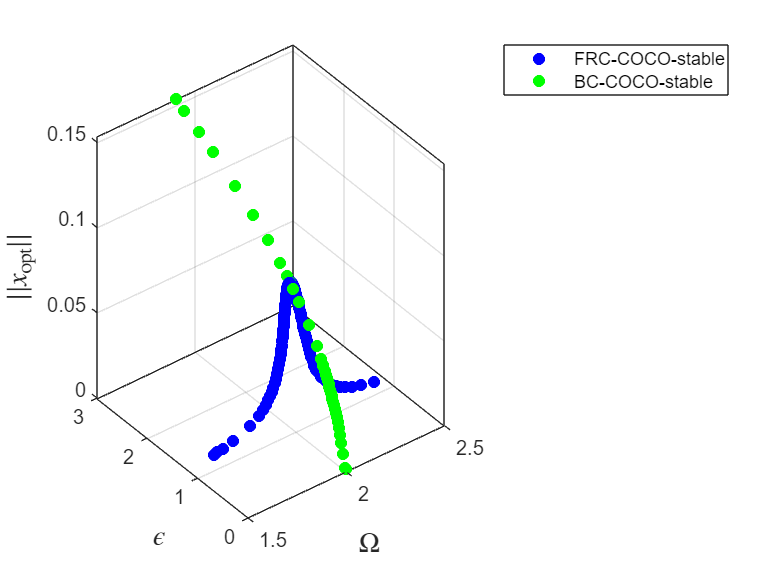

set(coco.Options, 'dir_name', 'l2'); % store results in folder named with linf...
coco.extract_damped_backbone(parRange,optdof);

#### Damped backbone curve using $\mathcal{L}^\infty$ norm


 Run='linf.phase': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.37e-02  5.87e+00    0.0    0.0    0.0
   1   1  1.00e+00  6.75e-02  3.28e-04  5.87e+00    0.0    0.0    0.0
   2   1  1.00e+00  4.80e-04  2.85e-08  5.87e+00    0.0    0.0    0.0
   3   1  1.00e+00  4.31e-08  3.37e-16  5.87e+00    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           obj           th    po.period        d.obj   d.po.tinit        d.eps      d.omega        omega          eps         amp1
    0  00:00:00   5.8668e+00      1  EP      1.3822e-02  -2.8561e-03   3.9270e+00   0.0000e+00   0.0000e+00   0.0000e+00   0.0000e+00   1.6000e+00   1.0000e+00   1.3900e-02
    7  00:00:01   7.3190e+00      2  FP     -1.3940e-02   3.0945e+00   3.9270e+00   0.0000e+00   0.0000e+00   0.0000e+00   0.0000e+00   1.6000e+00   1.0000e+00   1.3940

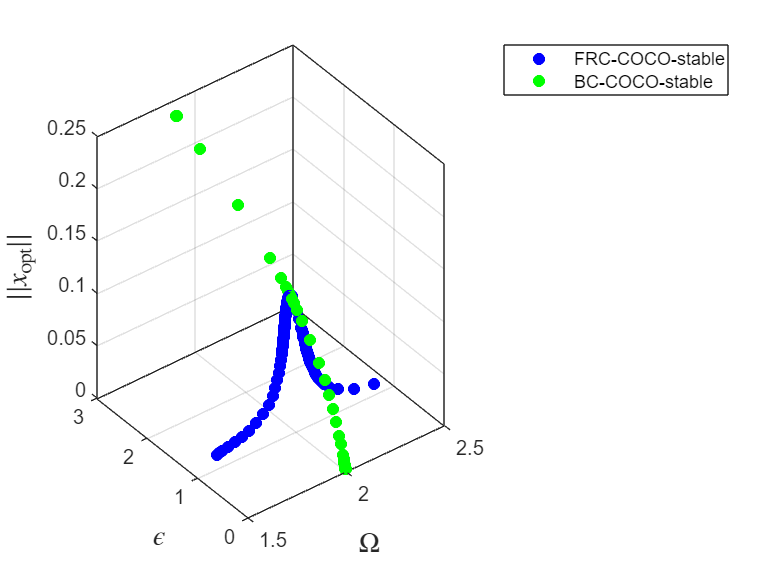

set(coco, 'optnorm', 'linf');
set(coco.Options, 'dir_name', 'linf'); % store results in folder named with linf...
coco.extract_damped_backbone(parRange,optdof);